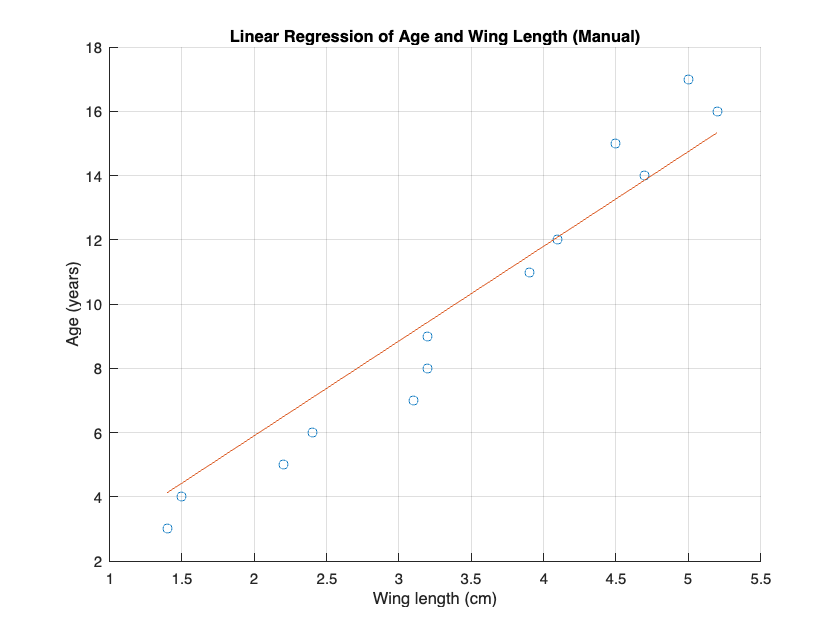

%Assume Wing length is the x variable and y Age is the  variable.
%Plot X vs Y. Plot the regression line.
age_vs_wing_length= [3	1.4
4	1.5
5	2.2
6	2.4
7	3.1
8	3.2
9	3.2
11	3.9
12	4.1
14	4.7
15	4.5
16	5.2
17	5.00];
X= age_vs_wing_length(:, 2);
Y= age_vs_wing_length(:, 1);
scatter(X, Y);
xlabel('Wing length (cm)')
ylabel('Age (years)')
title('Linear Regression of Age and Wing Length (Manual)')
grid on;
%Calculate the slope B of the regression and plot the linear regression
%line.
hold on
B=X\Y;
yCalc= B*X;
plot(X, yCalc)

Rsq1 = 1 - sum((Y - yCalc).^2)/sum((Y - mean(Y)).^2);
disp(Rsq1);

    0.9243



% hold on
% %Include a Y-intercept B_0
% X_0 = [ones(length(X),1) X];
% B_0 = X_0\Y;
% yCalc_0= X_0.*B_0';
% plot(X, yCalc_0(:, 2), '--');


%Test the Null hypothesis H0: b=0 with a two-tailed T-test
 ttest_result = ttest2(B, 0); %WHY DOES THIS GIVE NAN CAN YOU NOT INPUT SINGLE VALUES INTO T-TEST? HOW DO WE TEST IF B=0 IF NOT LIKE THIS?
 if ttest_result== 1;
     disp('The Null hypothesis can be rejected');
 end
 if ttest_result== 0;
     disp('The Null hypothesis has been supported');
end

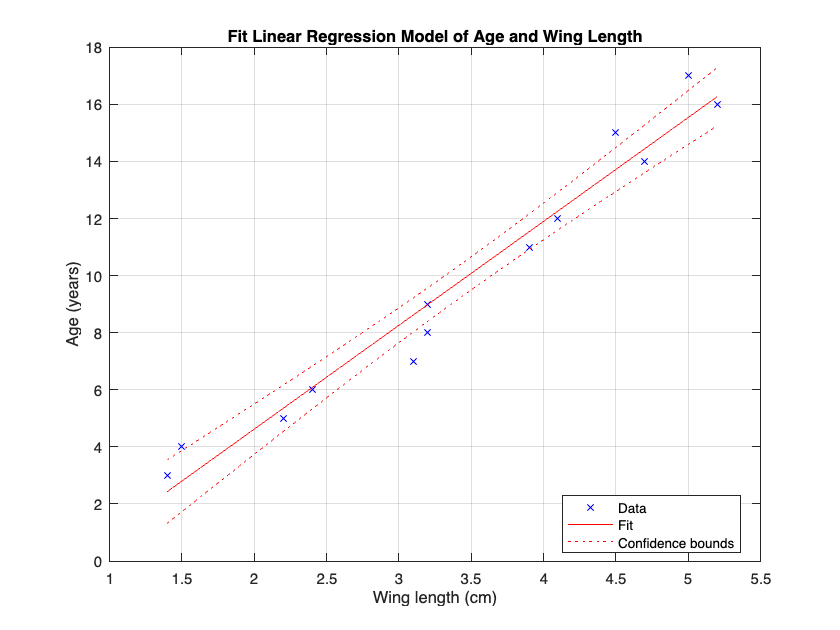

%Calculate and plot the Confidence intervals on the slope of the regression
figure()
lm= fitlm(X, Y);
plot(lm);
xlabel('Wing length (cm)')
ylabel('Age (years)')
title('Fit Linear Regression Model of Age and Wing Length')
grid on;

disp(lm.Rsquared);

    Ordinary: 0.9634
    Adjusted: 0.9601



%Calculate the Pearson's coefficient
pearsons= corrcoef(X, Y);
disp(pearsons(1, 2));

    0.9815



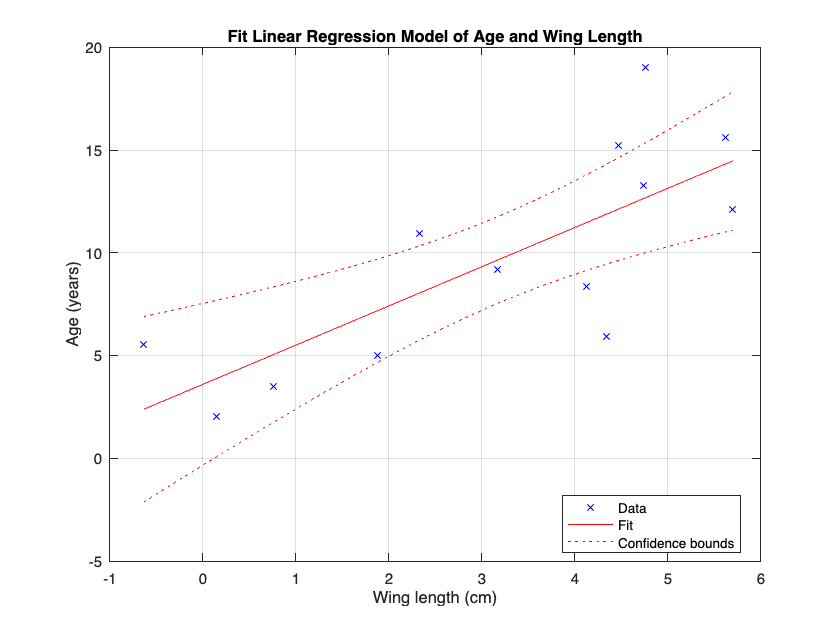

%Add noise to the data and look at regression
for i= 1:length(age_vs_wing_length);
    X1(i)= age_vs_wing_length(i, 2)+randn;
    Y1(i)= age_vs_wing_length(i, 1)+randn;
end
lmNoisy= fitlm(X1, Y1);
plot(lmNoisy);
xlabel('Wing length (cm)')
ylabel('Age (years)')
title('Fit Linear Regression Model of Age and Wing Length')
grid on;

disp(lmNoisy.Rsquared);

    Ordinary: 0.5954
    Adjusted: 0.5586

